# Trabajo de laboratorio integrador 1

Modelado de sistemas – Caracteristicas y medidas de desempeño

clearvars;  % Borra las variables de la memoria
close all;  % Cierra todas las ventanas de gráficos
clc;        % Limpia la pantalla de comandos

%Parámetros del circuito
C1 = 0.1e-6; R1 = 100e3;    
R2 = 47e3; C2 = 0.1e-6;  
R9 = 1e3; R7 = 10e3;    

s = tf('s');

### 1a. Función de trasferencia de los bloques

% Sys1
Sys1 = 1 / (R1 * C1 * s + 1)


Sys1 =
 
      1
  ----------
  0.01 s + 1
 
Continuous-time transfer function.


% Sys2
k = 1 + (R7 / R9);
Sys2 = k / (R2 * C2 * s + 1)


Sys2 =
 
       11
  ------------
  0.0047 s + 1
 
Continuous-time transfer function.


### Función de transferencia en lazo abierto G(s)

Gp = series(Sys1, Sys2) 


Gp =
 
              11
  --------------------------
  4.7e-05 s^2 + 0.0147 s + 1
 
Continuous-time transfer function.


### 1b. Función de transferencia del sistema realimentado 

%Sysf(s)
Sysf = feedback(Gp, 1)


Sysf =
 
              11
  ---------------------------
  4.7e-05 s^2 + 0.0147 s + 12
 
Continuous-time transfer function.


### 1c. Función de transferencia del sistema realimentado estándar

Sysf_zpk = zpk(Sysf)


Sysf_zpk =
 
         2.3404e+05
  -------------------------
  (s^2 + 312.8s + 2.553e05)
 
Continuous-time zero/pole/gain model.


[wn_vec, zeta_vec, polos] = damp(Sysf_zpk);

wn = wn_vec(1)     % Frecuencia angular [rad/s]

wn = 505.2912

xi = zeta_vec(1)   % Factor de amortiguamiento (ξ)

xi = 0.3095

## 2. Respuesta al escalón 

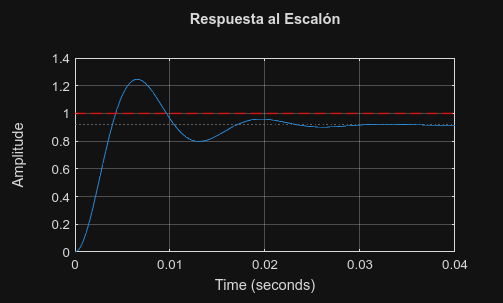

figure
step(Sysf)
yline(1, 'r--', 'LineWidth', 1.2, 'DisplayName', 'Entrada r(t) = 1 V'); % Entrada Escalón
grid on
title('Respuesta al Escalón')

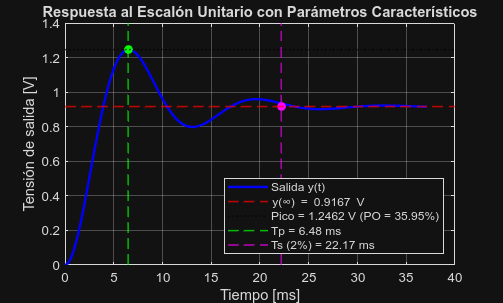


figure;
[y, t] = step(Sysf);
plot(t*1e3, y, 'b', 'LineWidth', 1.8); hold on;
grid on;

%parámetros característicos
info = stepinfo(Sysf, 'SettlingTimeThreshold', 0.02);
PO = info.Overshoot;
Tp = info.PeakTime;
Ts = info.SettlingTime;
y_inf = dcgain(Sysf);
y_pico = info.Peak;

% Marcado de líneas
yline(y_inf, 'r--', 'LineWidth', 1.2);   % Estado estacionario
yline(y_pico, 'k:', 'LineWidth', 1.1);   % Valor pico
xline(Tp*1e3, 'g--', 'LineWidth', 1.1);  % Tiempo de pico
xline(Ts*1e3, 'm--', 'LineWidth', 1.1);  % Tiempo de establecimiento

%Puntos destacados 
plot(Tp*1e3, y_pico, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 6);
plot(Ts*1e3, y_inf, 'mo', 'MarkerFaceColor', 'm', 'MarkerSize', 6);


title('Respuesta al Escalón Unitario con Parámetros Característicos');
xlabel('Tiempo [ms]');
ylabel('Tensión de salida [V]');

legend('Salida y(t)', ...
       sprintf('y(\\infty) = %.4f V', y_inf), ...
       sprintf('Pico = %.4f V (PO = %.2f%%)', y_pico, PO), ...
       sprintf('Tp = %.2f ms', Tp*1e3), ...
       sprintf('Ts (2%%) = %.2f ms', Ts*1e3), ...
       'Location', 'southeast');

info =stepinfo(Sysf); 
PO = info.Overshoot

PO = 35.9530

Tp = info.PeakTime

Tp = 0.0065

Ts = info.SettlingTime

Ts = 0.0222

tr = info.RiseTime

tr = 0.0026

## 3. Error estacionario 

Escalon unitario 

[y_step, t_step] = step(Sysf);
r_step = ones(size(t_step));

e_step_sim = r_step(end) - y_step(end); % Error simulado al final
e_step_teo = 1 / (1 + 11);              % Error teórico: 1/(1+Kp)

fprintf('Error Teórico : %.4f V\n', e_step_teo);

Error Teórico : 0.0833 V


fprintf('Error Simulado: %.4f V\n', e_step_sim);

Error Simulado: 0.0840 V


Rampa unitaria 

t_ramp = 0:1e-3:2;                  % Vector de tiempo hasta 2 segundos
u_ramp = t_ramp;                    % Entrada rampa u = t
y_ramp = lsim(Sysf, u_ramp, t_ramp); % Respuesta a la rampa

e_ramp_sim = u_ramp(end) - y_ramp(end); % Error al final del tiempo

fprintf('Error Teórico : Infinito (Inf)\n');

Error Teórico : Infinito (Inf)


fprintf('Error a t=2s  : %.4f V (sigue creciendo)\n', e_ramp_sim);

Error a t=2s  : 0.1678 V (sigue creciendo)


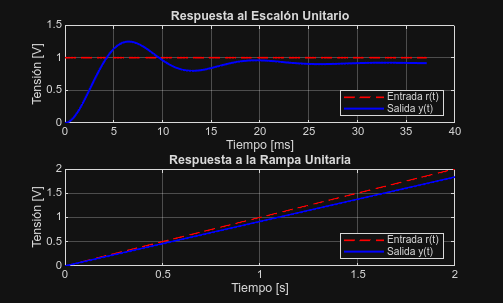

figure;

% Escalón 
subplot(2,1,1);
plot(t_step*1e3, r_step, 'r--', 'LineWidth', 1.2); hold on;
plot(t_step*1e3, y_step, 'b', 'LineWidth', 1.5);
grid on; 
title('Respuesta al Escalón Unitario'); 
xlabel('Tiempo [ms]'); 
ylabel('Tensión [V]');
legend('Entrada r(t)', 'Salida y(t)', 'Location', 'southeast'); 


% Rampa
subplot(2,1,2);
plot(t_ramp, u_ramp, 'r--', 'LineWidth', 1.2); hold on;
plot(t_ramp, y_ramp, 'b', 'LineWidth', 1.5);
grid on; 
title('Respuesta a la Rampa Unitaria'); 
xlabel('Tiempo [s]'); 
ylabel('Tensión [V]');
legend('Entrada r(t)', 'Salida y(t)', 'Location', 'southeast');

## 4. Valores comerciales

Dado que $ $k = 1 + \frac{R_7}{R_9}$$:   

- **Para **$$k = 1$$**:** $$R_7 = 0\ \Omega$ (cortocircuito) y $R_9 = \infty$ $(circuito abierto/no conectada).   

- **Para**$ $k = 3{,}2$: $R_7 = 22\text{ k}\Omega$ y $R_9 = 10\text{ k}\Omega$ $(ambos en E24) $$ k = 1 + \frac{22}{10} = 3{,}2$.   $

- **Para **$$k = 5{,}7$: $R_7 = 47\text{ k}\Omega$ y $R_9 = 10\text{ k}\Omega$$ (ambos en E24) $$ k = 1 + \frac{47}{10} = 5{,}7$.$   

- **Para**$ $k = 34$: $R_7 = 330\text{ k}\Omega$ y $R_9 = 10\text{ k}\Omega$$ (ambos en E24) $$ k = 1 + \frac{330}{10} = 34$.   $

% Datos de entrada pedidos por el enunciado
k_vals = [1; 3.2; 5.7; 34];
R7_vals = [0; 22e3; 47e3; 330e3];      
R9_vals = [Inf; 10e3; 10e3; 10e3];     

% Inicialización de columnas de la tabla
wn_vec    = zeros(4,1);
xi_vec    = zeros(4,1);
PO_vec    = zeros(4,1);
Tp_vec    = zeros(4,1);
Ts_vec    = zeros(4,1);
y_inf_vec = zeros(4,1);
ess_vec   = zeros(4,1);

for i = 1:length(k_vals)
    % Cálculo directo de k a partir de R7 y R9
    if R7_vals(i) == 0
        k = 1;
    else
        k = 1 + (R7_vals(i) / R9_vals(i));
    end
    
    % Función de transferencia en lazo cerrado
    G = (1 / (R1*C1*s + 1)) * (k / (R2*C2*s + 1));
    Sysf = feedback(G, 1);
    
    % Frecuencia natural y amortiguamiento
    [wn, zeta] = damp(Sysf);
    wn_vec(i) = wn(1);
    xi_vec(i) = zeta(1);
    
    % Parámetros temporales de la respuesta al escalón
    info = stepinfo(Sysf);
    PO_vec(i) = info.Overshoot;
    Tp_vec(i) = info.PeakTime;
    Ts_vec(i) = info.SettlingTime;
    
    % Estado estacionario y error
    y_inf_vec(i) = dcgain(Sysf);
    ess_vec(i)   = 1 - y_inf_vec(i);
end

% Generación de la Tabla final
Tabla_Punto4 = table(k_vals, R7_vals, R9_vals, wn_vec, xi_vec, PO_vec, Tp_vec, Ts_vec, y_inf_vec, ess_vec, ...
    'VariableNames', {'k', 'R7_Ohm', 'R9_Ohm', 'wn_rad_s', 'xi', 'PO_Porc', 'Tp_s', 'Ts_s', 'y_inf_V', 'ess_V'});
disp(Tabla_Punto4);

     k     R7_Ohm     R9_Ohm    wn_rad_s      xi       PO_Porc      Tp_s         Ts_s      y_inf_V     ess_V  
    ___    _______    ______    ________    _______    _______    _________    ________    _______    ________

      1          0      Inf      206.28     0.75809    2.5935      0.023264    0.027434        0.5         0.5
    3.2      22000    10000      298.93     0.52313    14.537      0.012368    0.025825     0.7619      0.2381
    5.7      47000    10000      377.56     0.41419     23.94     0.0091289    0.022257    0.85075     0.14925
     34    3.3e+05    10000      862.95     0.18122    55.722     0.0038282    0.023277    0.97143    0.